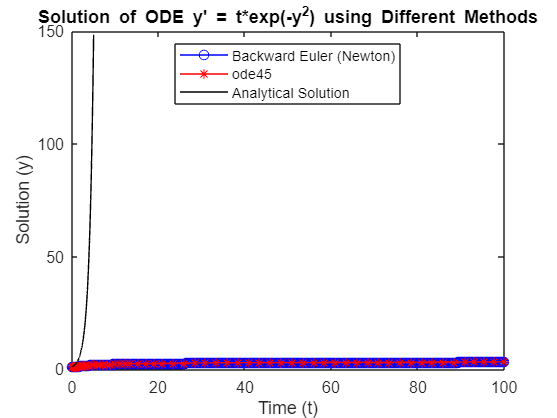

% Part D
f_4 = @(t,y) t*exp(-y^2);
df_4 = @(t, y) -2*t*y*exp(-y^2);
ic = 1;
tol = 50^-5;
tspan = [0 100];
nsteps = 1000;
[t_1d, y_1d] = backward_euler_newton(f_4,df_4,tspan,ic, nsteps,tol);
[t_4, y_4] = ode45(f_4, tspan, ic);

t_analytical_D = linspace(0,5,1000);
y_analytical_D = exp(t_analytical);

figure;
plot(t_1d,y_1d, 'b-o', t_4, y_4, 'r-*', t_analytical_D, y_analytical_D, 'k')
legend('Backward Euler (Newton)', 'ode45', 'Analytical Solution', 'Location', 'Best');
title('Solution of ODE y'' = t*exp(-y^2) using Different Methods');
xlabel('Time (t)');
ylabel('Solution (y)');